# Data processing tutorial

To open this page as a Matlab live script, run the command

This tutorial will walk you though the sequence of steps required to process data before getting to the stage where you want to carry out machine learning.

Why? Without processing, the data will most certainly not behave according to the [Beer-Lambert law](https://en.wikipedia.org/wiki/Beer%E2%80%93Lambert_law) in it's entirety.

First, we need to initialize this instance and load the dataset we already imported in one of the other tutorials ([simple import tutorial](matlab:open('./import_tutorial_01.html'))).

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;
load("tutorial_01_imported.mat")

The sequence suggested here is as outlined below. Each box describes the step (top header) and the method(s) of the toolbox that support the step.

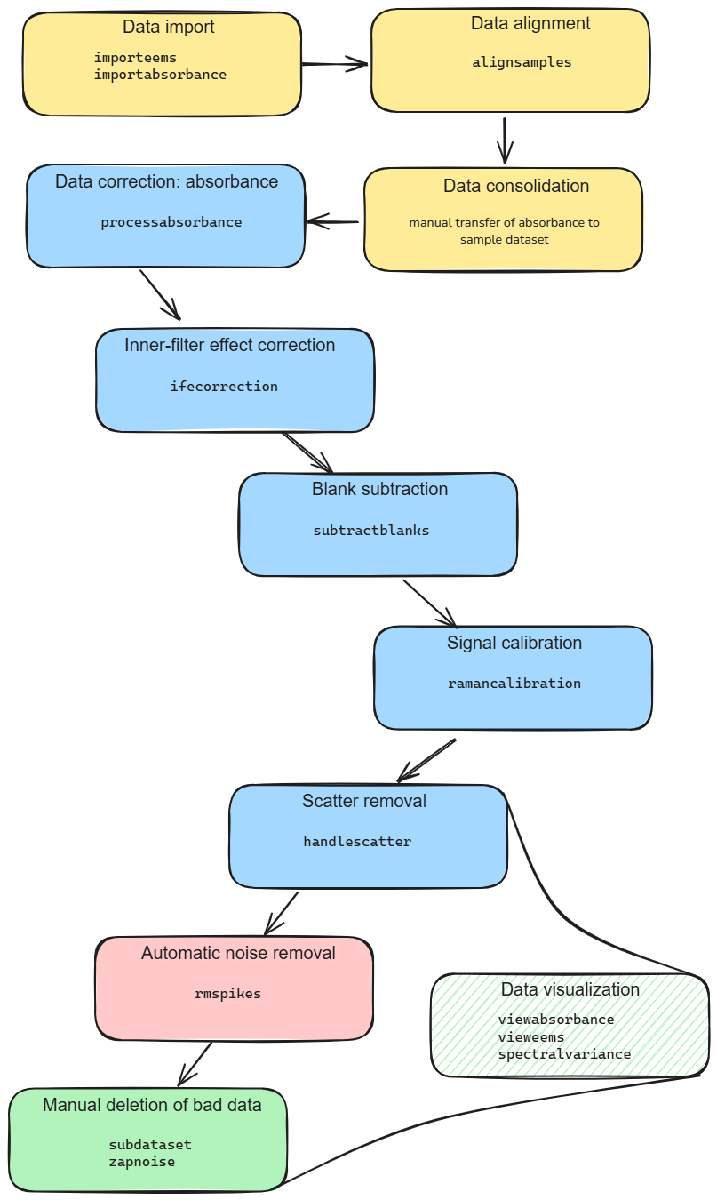

## Data quality control of absorbance data

Let's first take a look at our absorbance. This will do the trick:

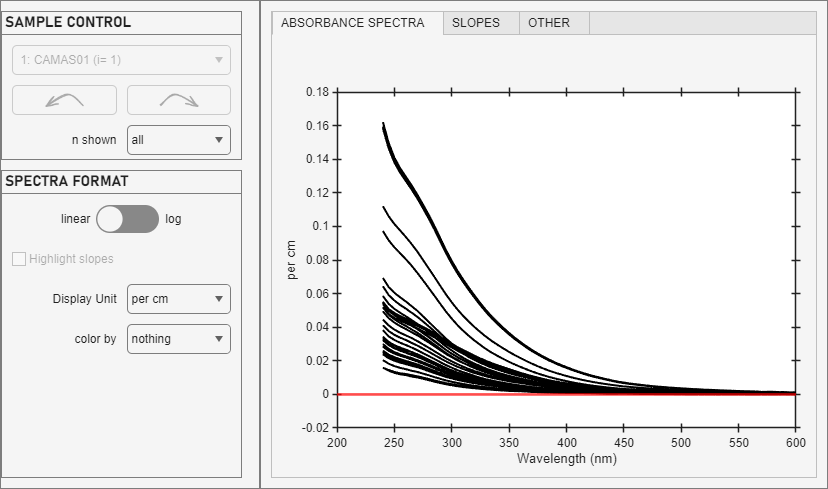

tbx.viewabsorbance(samples)

Take note of several things:

- We have absorbance *above 0.05 per cm*. So inner-filter effects are significant and need to be compensated.

- The spectra look quite typical for CDOM which is good news for data quality

- Some part of the spectra seems to go below zero. A baseline compensation would be a good idea in all likelyhood.

Let's get to the automated processing with [`processabsorbance`](matlab:open('processabsorbance.html')). In principle, the function can be called quite simply like this:

However, there are several options assumed as defaults and you'd have to read the documentation in order to know what they are. Did you click on it yet? Let's assume you didn't and we will therefore explicitly set the options:

EEMs were measured at wavelengths longer than CDOM spectra.


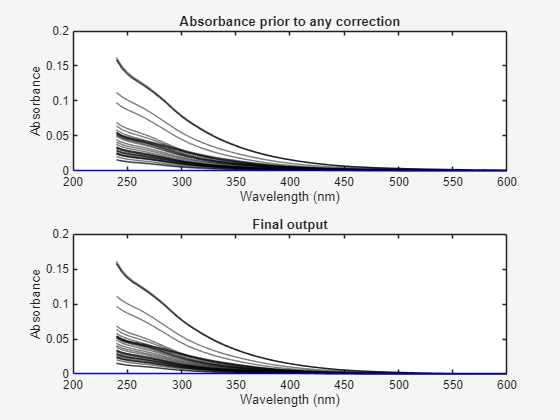

samples=tbx.processabsorbance(samples, ...
    "correctBase",true,...
    "baseWave",600,...
    "extrapolate",false,...
    "zero",true);

Based on our observation at the start, we simply want to do a baseline offset. I choose 600 nm here. No extrapolation (not relevant here since we cover all the way to 600 nm), and if, for some reason, some signals are below zero at the end, they'd be zero'ed. Doesn't look likely and it might be a better idea to leave the data as is. From an IFE correction perspecive, I'd rather have zeros to leave the EEM data unaffected.

The function output shows before and after. As you can see, the effects are minor. But nonetheless, we have now processed our absorbance data.

## Compensation of innter-filter effects

The inner-filter effect correction is straightforward and performed with [`ifecorrection`](matlab:open('ifecorrection.html')):

Abs-based IFE correction applied. CDOM and FDOM coverage different (subdataset applied). 


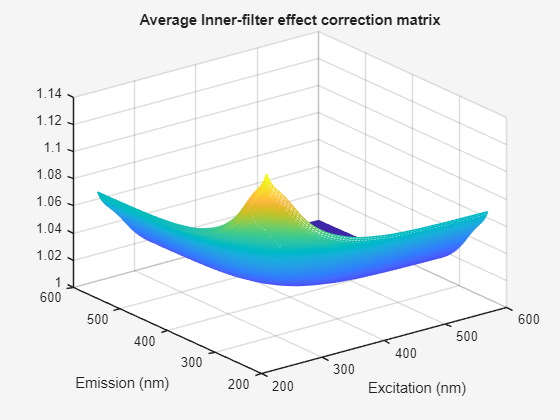

samples=tbx.ifecorrection(samples);

An important note is that the function will do some checks and automatically react based on these. 

- Don't worry about the units of your absorbance. ***If*** you supplied the correct information during import, the function does an automatic conversion.

- If the absorbance spectra don't cover the entire excitation and / or emission range, the EEM data not covered by absorbance that will be deleted. No option to disable this. If you want to circumvent this, set  `extrapolate=true `when using [`processabsorbance`](matlab:open('processabsorbance.html')). This will perform a CDOM-specific extrapolation based on the exponentially decaying absorbance toward long wavelengths. If you have non-CDOM-type data, this won't work. In any case, it's always a good idea to cover the entire EEM range with CDOM absorbance measurements. Then you don't have to worry about this sort of thing!

- If the absorbance is above values of 2 (assumed per cm by the function), the IFE correction factors will be replaced with NaN, resulting in missing data in the fluorescence EEMs. This is a conservative measure based on the fact that absorbance measurements of this magnitude become somewhat unreliable. It is recommended to dilute samples to avoid this issue.

## Subtraction of blanks

This is a straightforward operation that could easily be done manually with a line of code, but the function subtractblanks documents the fact that this subtraction has in fact taken place and shows some visual output that you can inspect to identify that the blanks actually looked fine. It's as simple as this:

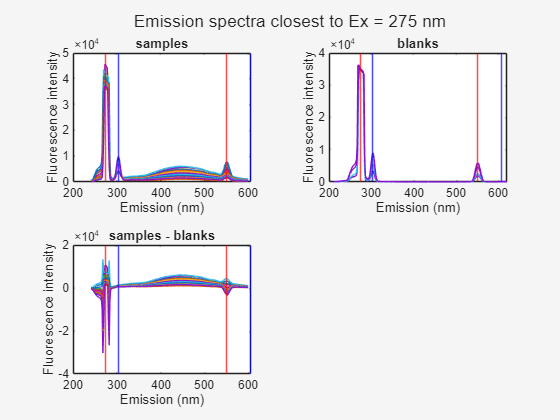

samples=tbx.subtractblanks(samples,blanks);

Take a look at the plot "blanks". If you see negative or large positive signals between the first blue and second red line in the graph, one or several of your blanks gave a fluorescence signal that might affect your dataset. In this case, you could chose to opt out of a blank subtraction. But whether or not that's a good idea is up for discussion.

One can see that the plot "samples - blanks" shows negative signals around the scatter lines (highlighted by the red and blue vertical lines). This simply means that there was more scatter in the blanks than in the samples and that the extent of scatter varied between the two dataset.

## Signal calibration

Next, it is time to calibrate the fluorescence singnals. This is done by dividing the signals by the area under the Raman peak (by default at Ex=350) in the blanks:

Raman normalization wavelength (350) found in EEM data.


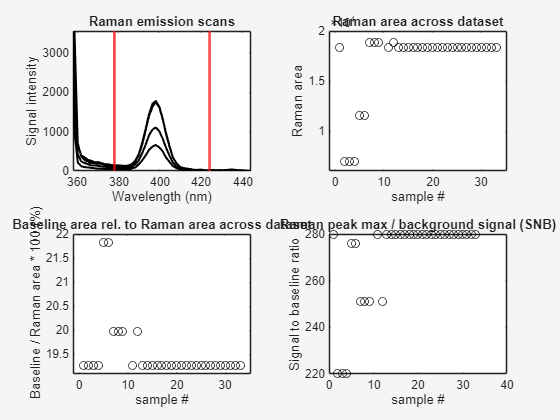

samples=tbx.ramancalibration(samples,blanks);

By default, the function assumes a certain emission window for this task and it is part of your task to verify that this range is appropriate. The output window's figure "Raman emission scans" shows the integration window with two vertical red lines. If you see that this window should change because it is too narrow or broad, the options `iStart` and `iEnd` (in nanometers) are there for this purpose.

By default, the function integrates the Raman peak at Ex=350. If this wavelength wasn't covered by your measurements, the function will interpolate the blank EEMs and integrate the interpolated spectrum.

The baseline signal is subtracted from the integrated area and the visualizations go into some depth on whether this baseline (compared to the area) changed a lot in your dataset. Have a close look at the output; this will directly affect fluorescence intensities extracted later!

## Scatter handling

On the topic of scatter handling, you have two functions at your disposal. [`viewscatter`](matlab:open('viewscatter.html')) can be called to visualize scatter and define the settings interactively. Take a look:

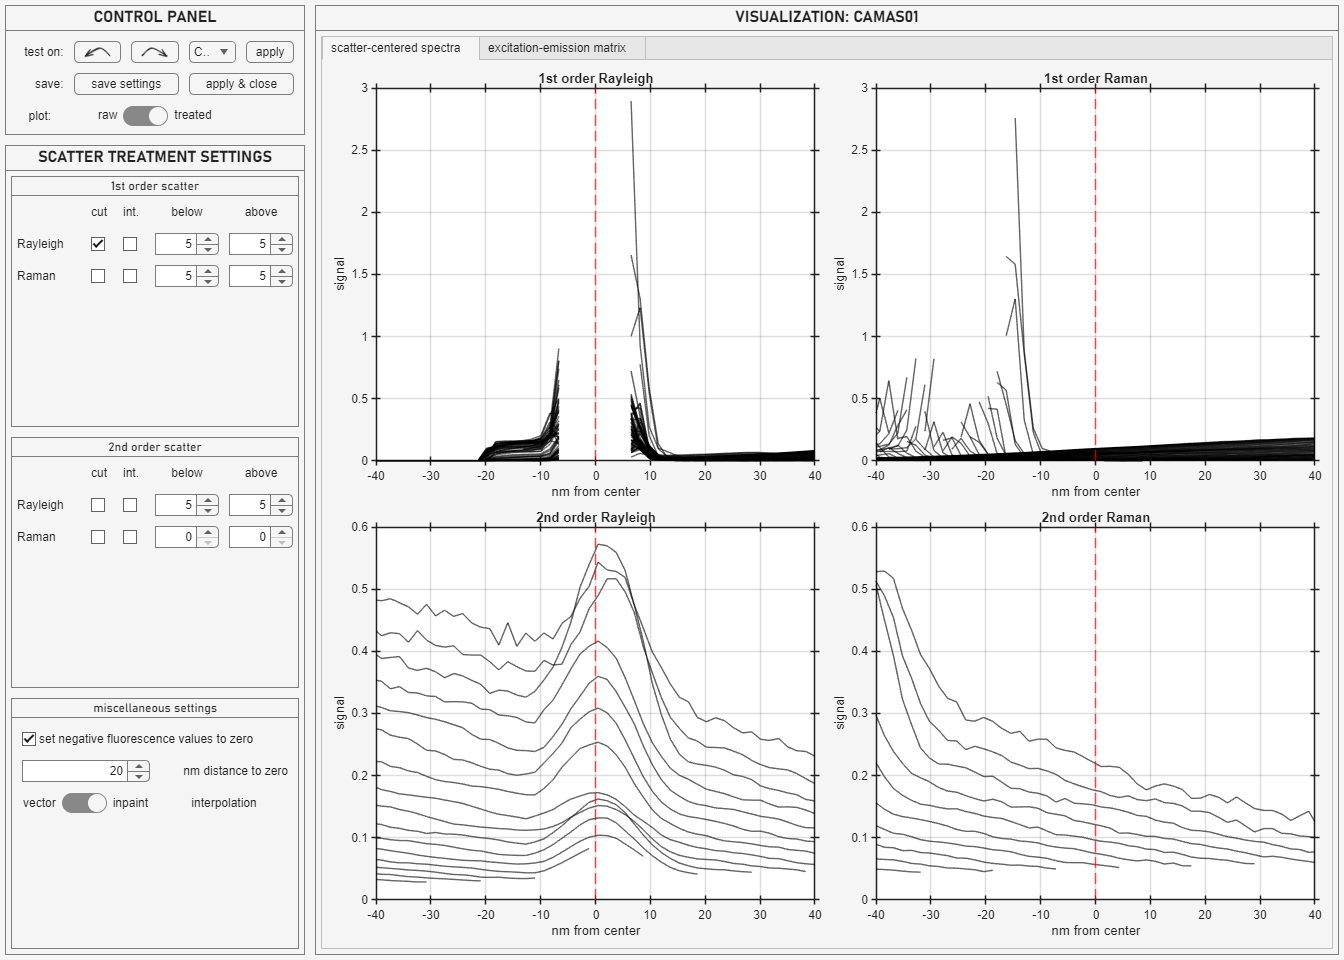

tbx.viewscatter(samples)

The app starts out with a somewhat strange visualization: The 4 types of scatter (1st and 2nd order Rayleigh and Raman) are shown in separate figures. In each, the data was modified to center the scatter at 0 nm and you are looking at emission scans. Lined up like this, it is apparent how far the scatter extends below and above. You can try settings on the left and then flip the switch to "treated" from "raw" to see the effect. If you change the settings, the plots will be updated. Change the tab to "excitation-emission matrix" from "scatter-centered spectra" to inspect the EEM in the way that you are used to. Change the settings until you are happy.

You can then export only the settings to the workspace and save them as a mat-file (recommented for reproducibility of the script), or hit "apply & close" to finish treating your dataset and move on. For the sake of the tutorial, we load some options and move on. You can define different options and apply them yourself of course.

load("processing_tutorial_01_scatterOpts.mat")
samples=tbx.handlescatter(samples,scatteroptions);

The scatter is removed with the function [`handlescatter`](matlab:open('handlescatter.html')) (as you could see above). Since we defined the options via `viewscatter`, the function does not output any results to inspect the success. We assume that you did that during the call to `viewscatter`. You could also call handlescatter like this:

This would call the same GUI that `viewscatter` provides, but the script execution waits for you to finish making your settings choices and then hands over the settings to `handlescatter` to apply them. Same result, different ways of getting there.

Time to clean up now. We no longer need the blank dataset. So we can delete it and also the variable `scatteroptions`. The settings are accessible and stored via the history of the dataset `samples`.

clearvars blanks scatteroptions

Take a look at what we've done so far:

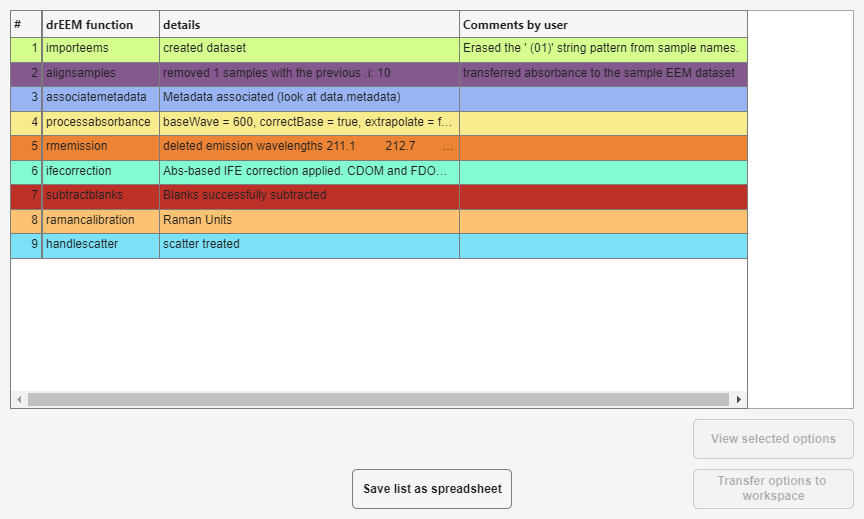

tbx.viewhistory(samples)

Now, there are quite a few entries. Clicking on a function in the list where options were provided (or defaults assumed) enables the button "View selected options". A separate window appears with the name of each option and it's corresponding setting. Here, you can see that the `ifecorrection` function called `subdataset` automatically to remove emission wavelengths that did not get covered by the absorbance scan. Suprise... (though I warned that this might happen).

## Deletion of unreliable or otherwise problematic EEM areas

At this point, we should take a look at the EEMs!

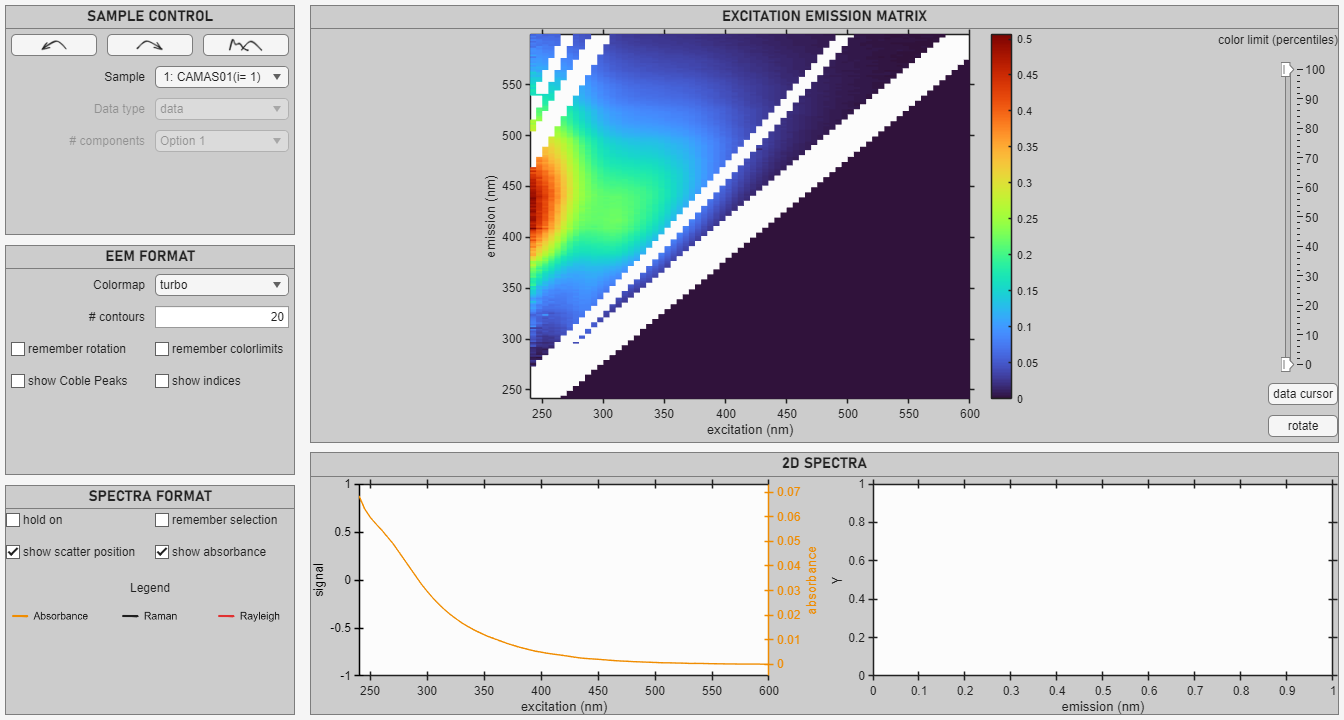

tbx.vieweems(samples)

Right away, we can see that our EEMs look quite nice. Not too noisy, pretty typical for NOM EEMs, no strange features. Though, not an aweful lot of data at excitation > 450 nm and no useful data below emission approx. 300 nm. To delete these data, we use [`subdataset`](matlab:open('subdataset.html')).

For this, we need to use logical statements:

disp(find(samples.Em<300))

     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37



This shows us that we would delete the first 37 emission wavelengths from the dataset. Let's use two calls, one for emission, one for excitation (though this could be combined into one):

samples=tbx.subdataset(samples,outEm=samples.Em<300);
samples=tbx.subdataset(samples,outEx=samples.Ex>450);

Then we take another look:

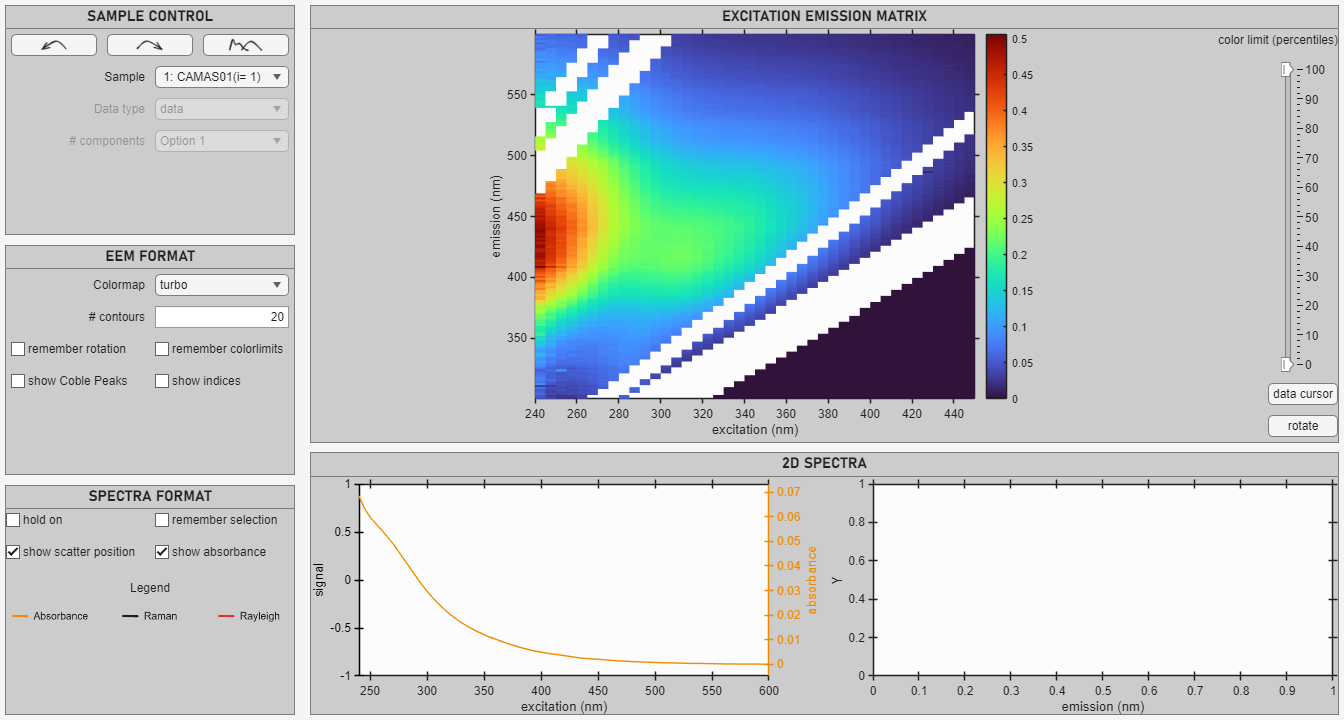

tbx.vieweems(samples)

Looks quite good now. Ready for some more analysis now! Let's save this dataset for later use.

save("tutorial_01_processed.mat","samples")
%close all force % Clean up with all these UI figure windows present